f = @(x) 3*sin(0.5*x+3) + 4*cos(5*x+2);

x1 = 0;
x2 = 10;

n_el = 10;

X = linspace(x1, x2, n_el);

X_test = linspace(x1, x2, 1000);
y_test = f(X_test);

X_rand = (x2-x1)*rand(n_el,1)+x1;

y = f(X);
y_rand = f(X_rand);

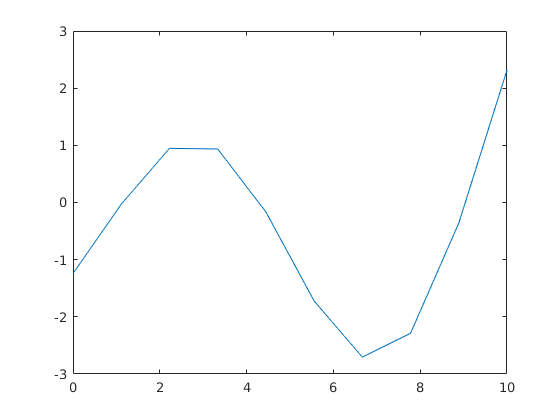

plot(X, y)
hold on

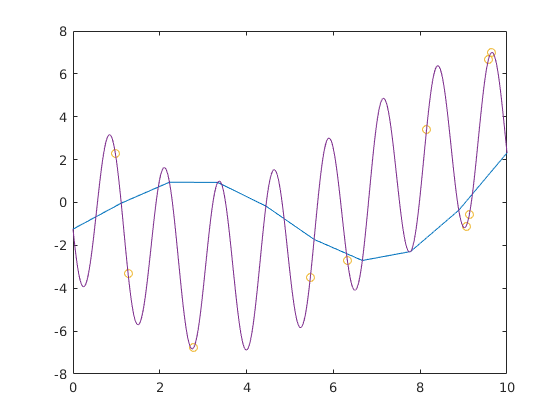

scatter(X_rand, y_rand)
hold on
plot(X_test, y_test)
hold on;

%ssn
net = feedforwardnet(10, 'trainbr');

view(net)

net = configure(net, X, y)

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 31
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConn

view(net)

net = train(net, X, y);

view(net)

net.IW{1,1}

ans =    -6.4117
    6.8324
    6.5947
   -6.6539
    6.5940
   -6.5969
   -6.6369
    6.5805
    6.5529
    6.5298


net.layers{1}

ans =     Neural Network Layer
 
              name: 'Hidden'
        dimensions: 10
       distanceFcn: (none)
     distanceParam: (none)
         distances: []
           initFcn: 'initnw'
       netInputFcn: 'netsum'
     netInputParam: (none)
         positions: []
             range: [10x2 double]
              size: 10
       

y_pred = net(X_test)

y_pred =    -0.9200   -0.9174   -0.9147   -0.9119   -0.9091   -0.9062   -0.9032   -0.9001   -0.8970   -0.8938   -0.8905   -0.8872   -0.8837   -0.8802   -0.8766   -0.8729   -0.8691   -0.8652   -0.8613   -0.8572   -0.8531   -0.8488   -0.8445   -0.8400   -0.8355   -0.8308   -0.8261   -0.8213   -0.8163   -0.8113   -0.8061   -0.8008   -0.7954   -0.7899   -0.7843   -0.7786   -0.7728   -0.7668   -0.7607   -0.7546   -0.7482   -0.7418   -0.7353   -0.7286   -0.7218   -0.7149   -0.7078   -0.7007   -0.6934   -0.6859


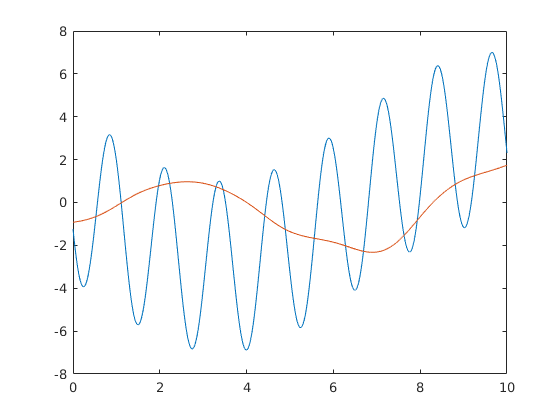

plot_data(net, X_test, y_test);

my_mse = @(X_, X_prim) sum((X_-X_prim).^2)*1/length(X_)

my_mse = function_handle with value:
    @(X_,X_prim)sum((X_-X_prim).^2)*1/length(X_)


my_mse(y_test, y_pred)

ans = 13.5298

n_perceptrons = [1, 5, 10, 20, 50];

activations = {'trainbr', 'trainbfg', 'trainrp', 'trainscg'};

y_trains = cell(5,1);
X_trains=  cell(5,1);

n_els = [10, 20, 50, 100, 200];

for i = 1:5
    X_trains{i} = linspace(x1, x2, n_els(i));
    y_trains{i} = f(X_trains{i});
end

ln = get_net('trainlm', n_perceptrons, X_trains, y_trains)

ln = 5×5 cell array
    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}
    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}
    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}
    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}
    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}


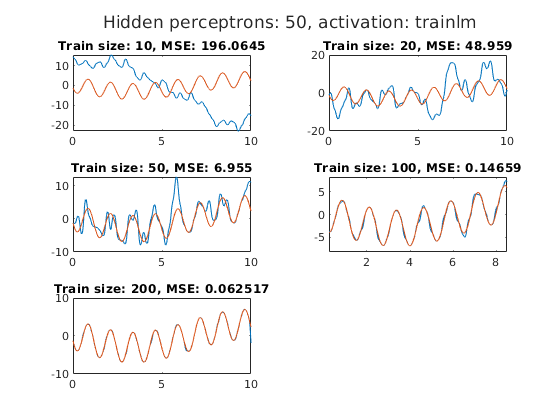

describe_net( ...
    ln(5,:), ...
    X_test, ...
    y_test, ...
    my_mse, ...
    'trainlm' ...
);

br = get_net('trainbr', n_perceptrons, X_trains, y_trains);

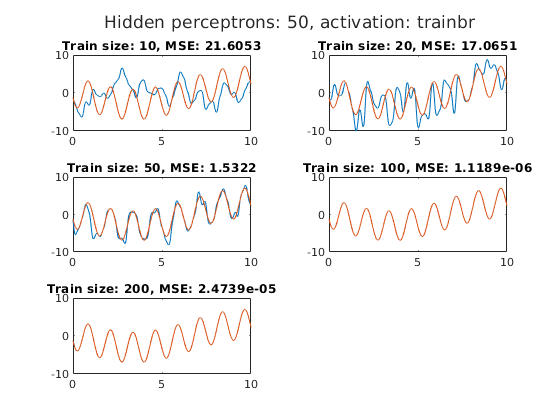

describe_net( ...
    br(5,:), ...
    X_test, ...
    y_test, ...
    my_mse, ...
    'trainbr' ...
);

bfg = get_net('trainbfg', n_perceptrons, X_trains, y_trains);

ans = 1×5 cell array
    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}    {1×1 network}


rp = get_net('trainrp', n_perceptrons, X_trains, y_trains);

scg = get_net('trainscg', n_perceptrons, X_trains, y_trains);

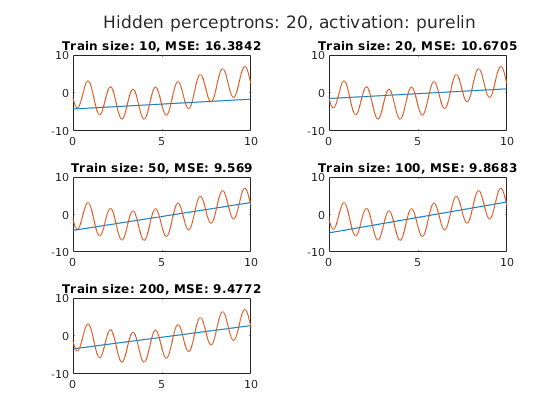

%% lin nets:

lin_nets = get_net('purelin', 'trainlm', n_perceptrons, X_trains, y_trains);

ans =    -1.0072
   -0.3952
   -0.7548
   -0.8218
    0.1517
   -0.9172
    0.6778
   -0.7856
   -0.1209
   -0.6470


describe_net( ...
    lin_nets(4,:), ...
    X_test, ...
    y_test, ...
    my_mse, ...
    'purelin' ...
);

lin_nets{5,2}.IW{1}

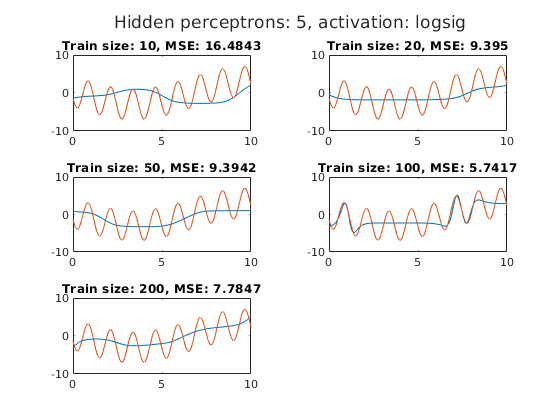

logsig_nets = get_net('logsig', 'trainlm', n_perceptrons, X_trains, y_trains);

describe_net( ...
    logsig_nets(2,:), ...
    X_test, ...
    y_test, ...
    my_mse, ...
    'logsig' ...
);